# Why won't we use Ideal Low Pass Filter?

Suppose that we have a continuous stream of data and we have only enough memory to simultaneously store and process sliding window of size N of incoming data. This is similar to what we do in FPGAs we are using in the laboratory, where you only process some part of the data at the same time. We want to apply a low pass filter to incoming data for our signal processing applications. Using an ideal low pass filter (i.e. having frequency response as 1 in low-pass region 0 otherwise) seems a viable choice. However, this will not be the case as we will see in this .mlx file.

## Ideal Low Pass Filter

Since we have finite number of points, in this case N number of points, we will use a low-pass filter of size N. Let us say we have cutoff frequency of $\omega_{cutoff}$. Let us write the frequency response of this lowpass filter as


$$X(\omega) = \begin{cases} 1 ,& \text{ if } |\omega| < \omega_{cutoff} \\ 0 ,& \text{o.w.} \end{cases}$$


Let us implement this filter in MATLAB.

% Clear remnant variables and graphs from previous work
clc;
clear;
close all;

Choose number of points in the data, i.e. specify N.

% Number of discrete points
N = 10;

Create corresponding discrete frequency values in DFT.

% Discrete frequency values
w = linspace(0,2*pi*(1-1/N),N);

Specify $\omega_{cutoff}$.

% Specify cutoff_frequency
cutoff_frequency = pi/5;

Specify ideal lowpass filter according to equation $X(\omega) = \begin{cases} 1 ,& \text{ if } |\omega| < \omega_{cutoff} \\ 0 ,& \text{o.w.} \end{cases}$.

% Create ideal low pass filter
ideal_lowpass_filter = (cutoff_frequency >= w) | (2*pi-cutoff_frequency <= w);
ideal_lowpass_filter = double(ideal_lowpass_filter);

Plot the resulting lowpass filter in the frequency domain.

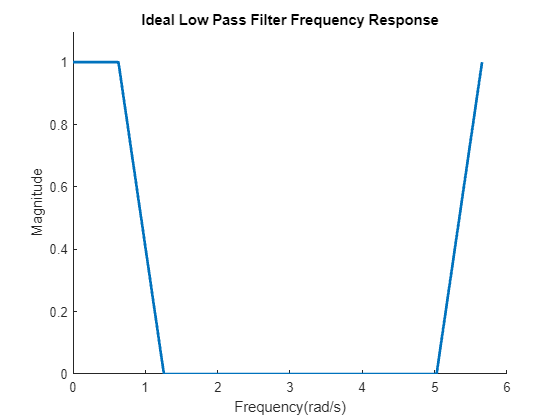

% Plot
figure;
hold on;
plot(w,ideal_lowpass_filter,'LineWidth',2);
title('Ideal Low Pass Filter Frequency Response');
xlabel('Frequency(rad/s)');
ylabel('Magnitude');
ylim([0,1.1]);

Acquire the lowpass filter in time and plot.

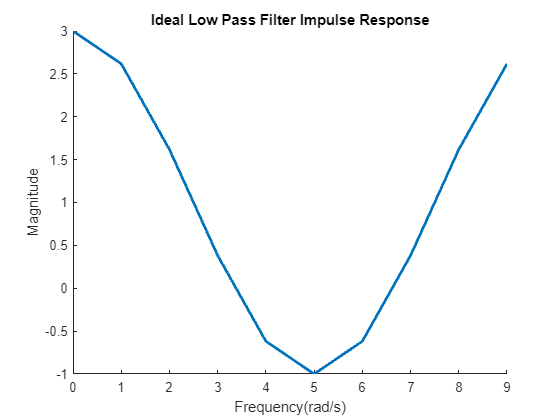

% Low pass filter in time
ideal_lowpass = fft(ideal_lowpass_filter);

% Plot
figure;
hold on;
plot(0:N-1, ideal_lowpass,'LineWidth',2);
title('Ideal Low Pass Filter Impulse Response');
xlabel('Frequency(rad/s)');
ylabel('Magnitude');

Now in this section we will write a code to see what happens to our frequency response of our ideal low pass filter if we increase the number of points. Since we will have continuous stream of points we expect it to have a similar response overall.

First use the symbolic library to obtain a polynomial representaion of the filter in the frequency domain. You can find polynomial_creator at the end of the file.

syms omega;
ideal_lowpass_dtft = 1/N*polynomial_creator(ideal_lowpass,exp(-1i*omega));

We first sample points from this frequency response to see we implement the equation true.

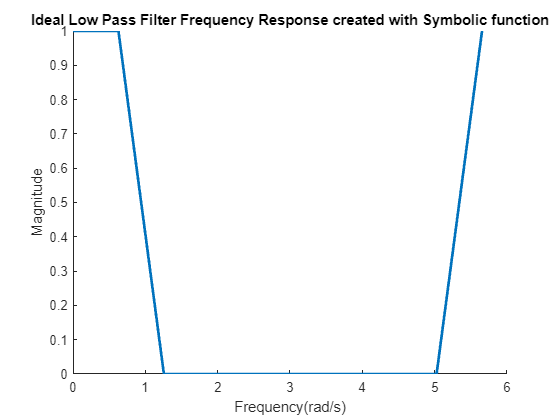

% Check that frequency response is same
ideal_lowpass_same = double(subs(ideal_lowpass_dtft,omega,w));

% Plot
figure;
hold on;
plot(w, abs(ideal_lowpass_same),'LineWidth',2);
title('Ideal Low Pass Filter Frequency Response created with Symbolic function');
xlabel('Frequency(rad/s)');
ylabel('Magnitude');

Now we sample with finer grid to see the frequency response when N2 = 200, i.e. what is the overall frequency response of the ideal lowpass filter when we take 20 windows and apply it to the data stream for our sliding windows.

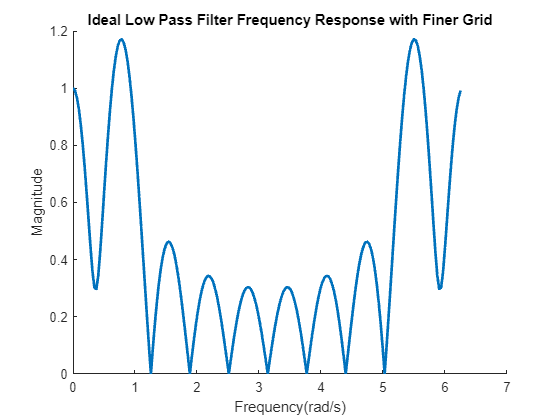

% Obtain finer grid of frequency
N2 = 200;
w2 = linspace(0,2*pi*(1-1/N2),N2);

ideal_lowpass_finer = double(subs(ideal_lowpass_dtft,omega,w2));

% Plot
figure;
hold on;
plot(w2, abs(ideal_lowpass_finer),'LineWidth',2);
title('Ideal Low Pass Filter Frequency Response with Finer Grid');
xlabel('Frequency(rad/s)');
ylabel('Magnitude');

As can be seen in the last plot, the frequency response has been dramatically changed, when we increase the number of points. This is what happens when you apply your ideal low pass filter to continuous data stream. It will not behave what we have desired it to behave.

The reason of this is that the ideal lowpass filter is in the first place is non causal and has infinite support, i.e. uses points we have not observed and nonzero at infinite points. However, the one we have created here is a causal one and even if increase the number of points will not converge to ideal behaviour we desire. You can increase the N and see this behaviour will continue for larger Ns. (Note: Since it uses symbolic toolbox choosing N higher than 200 will last long.).To overcome this problem we will not use ideal low pass filter rather we will use some rational polynomial filters that have nice properties that will not change if we increase the number of points. Moreover, they are causal filters. One of those filters is called Butterworth filter as we will mention below.

## Butterworth Filter

A particular choice we can use is the Butterworth filter, that has desirable properties for this problem and it is causal. It has the form as MATLAB tutorial suggests


$$X(z) = \frac{b(1) + b(2)z^{-1} + \dots + b(n)z^{-n}}{a(1) + a(2)z^{-1} + \dots + a(n)z^{-n}}}$$


where n is the order of the filter. 

Now create a Butterworth filter with order n and cutoff frequency of $\omega_{cutoff}$.

order = 6;
[b,a] = butter(order,cutoff_frequency/pi);

Create symbolic function for butterworth filter in frequency.

nom = polynomial_creator(b, exp(-1i*omega));
denom = polynomial_creator(a, exp(-1i*omega));

butterworth_filter_freq = nom/denom;

Take N samples from DTFT.

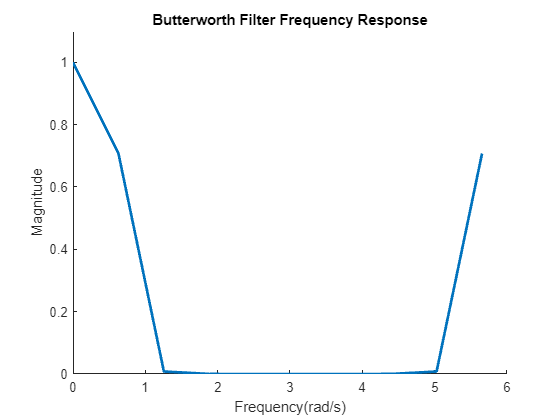

butterworth_filter_same = double(subs(butterworth_filter_freq,omega,w));

% Plot
figure;
hold on;
plot(w, abs(butterworth_filter_same),'LineWidth',2);
title('Butterworth Filter Frequency Response');
xlabel('Frequency(rad/s)');
ylabel('Magnitude');
ylim([0,1.1]);

Take N2 samples from DTFT.

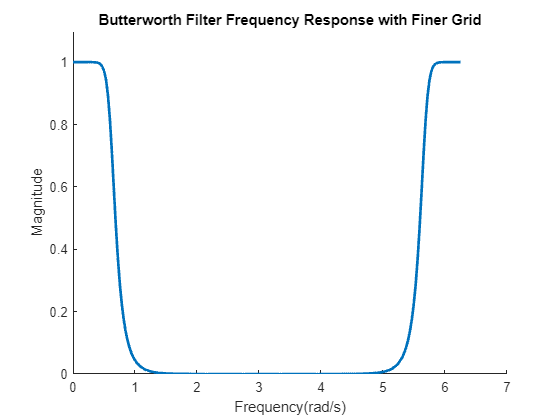

butterworth_filter_finer = double(subs(butterworth_filter_freq,omega,w2));

% Plot
figure;
hold on;
plot(w2, abs(butterworth_filter_finer),'LineWidth',2);
title('Butterworth Filter Frequency Response with Finer Grid');
xlabel('Frequency(rad/s)');
ylabel('Magnitude');
ylim([0,1.1]);

Since Butterworth filter is designed to have a property of low-pass filter on DTFT domain, it has lowpass characteristics even if we have increased the number of samples. Therefore, for such applications using designed filters are crucial.  

#### Auxilary Functions

function out = polynomial_creator(input, z)

    out = 0;

    for n = 0 : length(input)-1
        out = out + input(n+1)*z^n;
    end

end